Stacked graphs

Now reading Push\push1.mat


Now reading Push\push10.mat


Now reading Push\push2.mat


Now reading Push\push3.mat


Now reading Push\push4.mat


Now reading Push\push5.mat


Now reading Push\push6.mat


Now reading Push\push7.mat


Now reading Push\push8.mat


Now reading Push\push9.mat


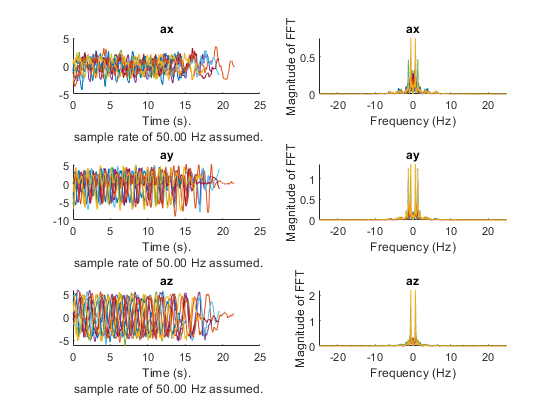

myDir = "Push"; %gets directory with 180 files
myFiles = dir(fullfile(myDir,'*.mat')); %gets all .mat files in struct

for k = 1:length(myFiles)
    baseFileName = myFiles(k).name;
    fullFileName = fullfile(myDir, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    
    [push] = ParseMatlabApp(fullFileName);
    t = push.t_Accel; 
    accel = push.Accel;
    
    secondsToTrim = 5;
    [t, accel] = trim_accel_data(t, accel, secondsToTrim);
    
    Fs = 50;    
    reduction_range = 0.1;
    ax = reduce_gravity(moving_avg(accel(:,1)), Fs, reduction_range);
    ay = reduce_gravity(moving_avg(accel(:,2)), Fs, reduction_range);
    az = reduce_gravity(moving_avg(accel(:,3)), Fs, reduction_range);
    
    N = size(accel);
    N = N(1);
    f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
    
    subplot(3,2,1)
    hold on
    
    make_time_plot(ax, Fs, 'ax')
    subplot(3,2,2)
    hold on
    make_freq_plot(ax, Fs, 'ax')
    
    subplot(3,2,3)
    hold on
    make_time_plot(ay, Fs, 'ay')
    subplot(3,2,4)
    hold on
    make_freq_plot(ay, Fs, 'ay')
    
    subplot(3,2,5)
    hold on
    make_time_plot(az, Fs, 'az')
    subplot(3,2,6)
    hold on
    make_freq_plot(az, Fs, 'az')
      % all of your actions for filtering and plotting go here
end

Individual graphs

Now reading Push\push1.mat


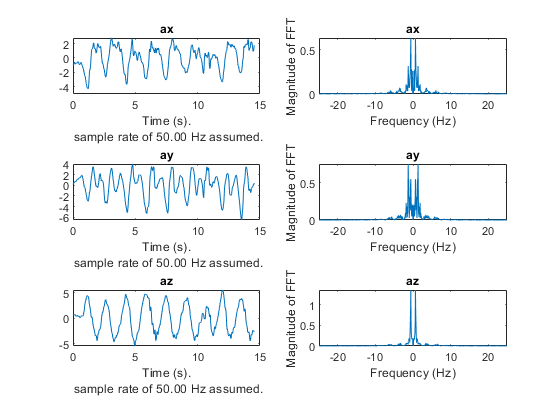

Now reading Push\push10.mat


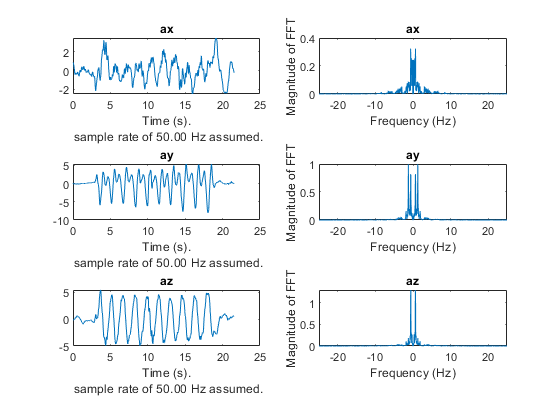

Now reading Push\push2.mat


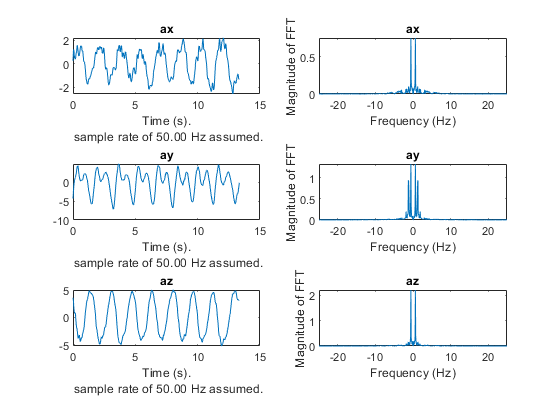

Now reading Push\push3.mat


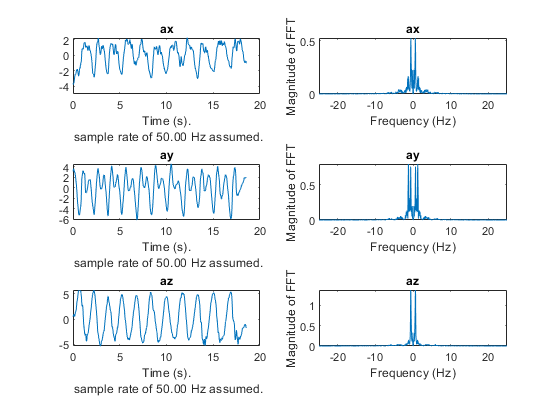

Now reading Push\push4.mat


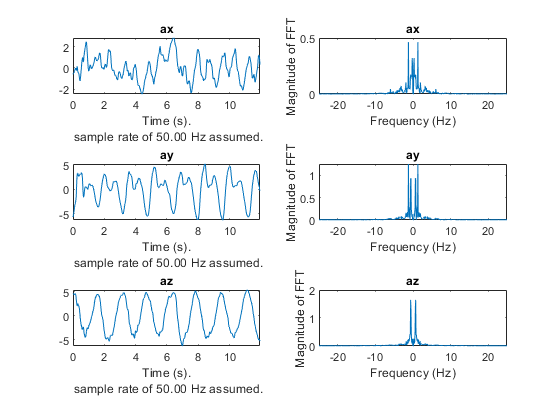

Now reading Push\push5.mat


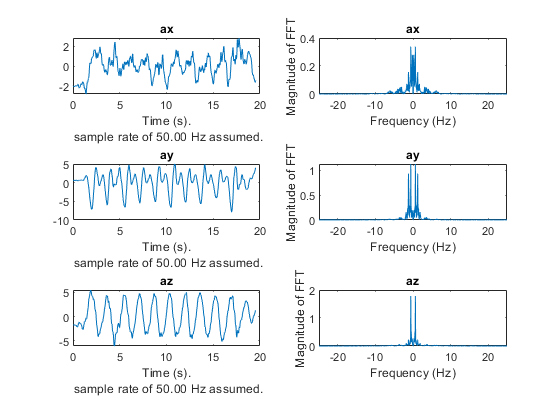

Now reading Push\push6.mat


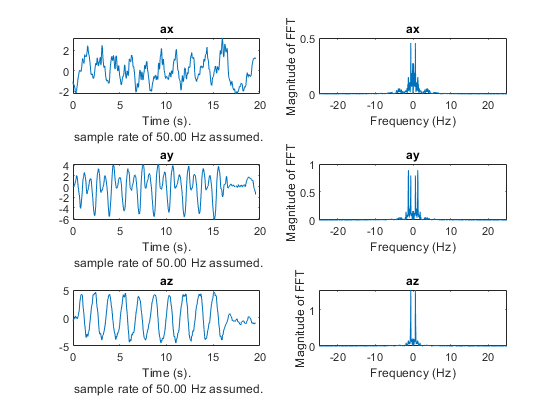

Now reading Push\push7.mat


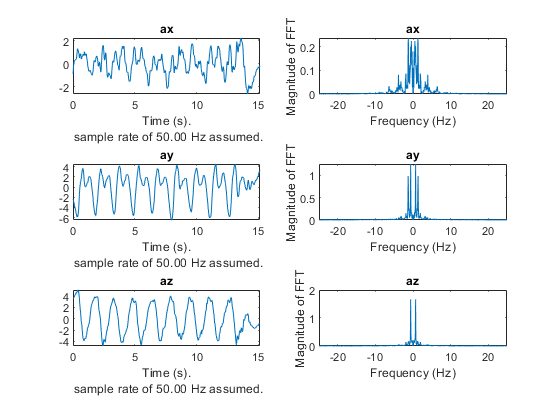

Now reading Push\push8.mat


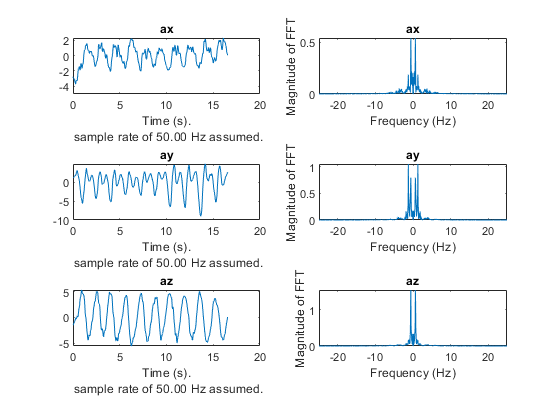

Now reading Push\push9.mat


myDir = "Push"; %gets directory with 180 files
myFiles = dir(fullfile(myDir,'*.mat')); %gets all .mat files in struct
for k = 1:length(myFiles)
    baseFileName = myFiles(k).name;
    fullFileName = fullfile(myDir, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    
    [push] = ParseMatlabApp(fullFileName);
    t = push.t_Accel; 
    accel = push.Accel;
    
    secondsToTrim = 5;
    [t, accel] = trim_accel_data(t, accel, secondsToTrim);
    
    Fs = 50;    
    reduction_range = 0.1;
    ax = reduce_gravity(moving_avg(accel(:,1)), Fs, reduction_range);
    ay = reduce_gravity(moving_avg(accel(:,2)), Fs, reduction_range);
    az = reduce_gravity(moving_avg(accel(:,3)), Fs, reduction_range);

    N = size(accel);
    N = N(1);
    f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
    figure
    hold on
    subplot(3,2,1)
    
    make_time_plot(ax, Fs, 'ax')
    subplot(3,2,2)
    make_freq_plot(ax, Fs, 'ax')
    
    subplot(3,2,3)
    make_time_plot(ay, Fs, 'ay')
    subplot(3,2,4)
    make_freq_plot(ay, Fs, 'ay')
    
    subplot(3,2,5)
    make_time_plot(az, Fs, 'az')
    subplot(3,2,6)
    make_freq_plot(az, Fs, 'az')
      % all of your actions for filtering and plotting go here
end

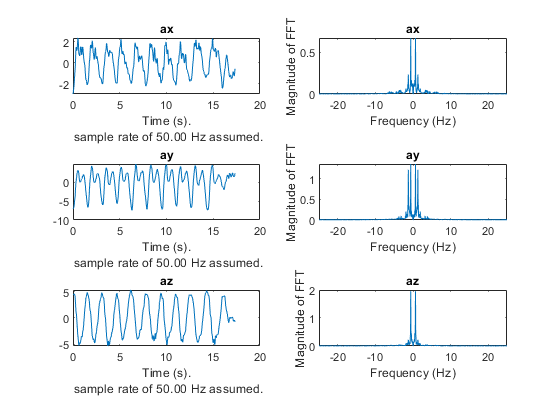

hold off